Fractional Replication of the 2k Design

Fractional Replication of the $2^3$ Tool Life Experiment (Prob. 8.2) Resolution III example

Fractional factorial design $2^{3-1} = 2^2 = 4 runs$

Step 1.

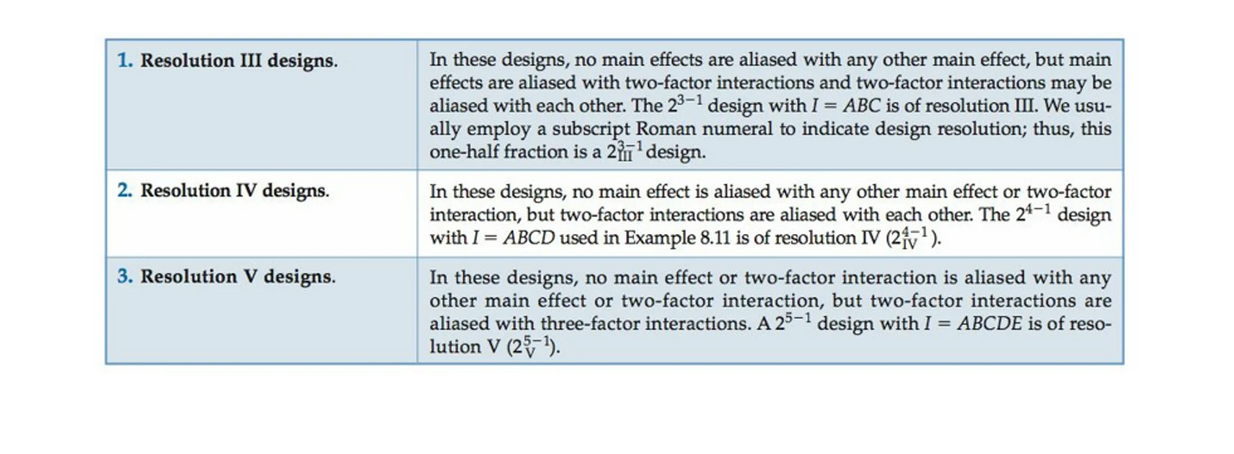

imshow('DesignResolution.png')

% See pg. 395 of your textbook

generators = fracfactgen('a b c', 2, 3)

generators = 3×1 cell array
    {'a' }
    {'b' }
    {'ab'}


% These are generators for the three-factor design with factors a,b,c,
% using 2^2 = 4 runs to achieve resolution III.

Step 2. Fractional factorial design

[dfF, confounding] = fracfact(generators)

dfF =     -1    -1     1
    -1     1    -1
     1    -1    -1
     1     1     1


confounding = 7×3 cell array
    {'Term' }    {'Generator'}    {'Confounding'}
    {'X1'   }    {'a'        }    {'X1 + X2*X3' }
    {'X2'   }    {'b'        }    {'X2 + X1*X3' }
    {'X3'   }    {'ab'       }    {'X3 + X1*X2' }
    {'X1*X2'}    {'ab'       }    {'X3 + X1*X2' }
    {'X1*X3'}    {'b'        }    {'X2 + X1*X3' }
    {'X2*X3'}    {'a'        }    {'X1 + X2*X3' }


Step 3. Create a table to hold the DOE test matrix

tlife1 = [440;354;325;392]; % Replicate 1
tlife2 = [453;348;435;419]; % Replicate 2
tble = table([dfF(:,1);dfF(:,1)],[dfF(:,2);dfF(:,2)],[dfF(:,3);dfF(:,3)],[tlife1;tlife2],'VariableNames',{'CuttingSpeed','MetalHardness','CuttingAngle','ToolLife'})

tble = 8×4 table
    CuttingSpeed    MetalHardness    CuttingAngle    ToolLife
    ____________    _____________    ____________    ________

         -1              -1                1           440   
         -1               1               -1           354   
          1              -1               -1           325   
          1               1                1           392   
         -1              -1                1           453   
         -1               1               -1           348   
          1              -1               -1           435   
          1               1                1           419   


Step 4. Linear regression model

mdl = fitlm(tble,'ToolLife ~ CuttingSpeed + MetalHardness + CuttingAngle')

mdl = Linear regression model:
    ToolLife ~ 1 + CuttingSpeed + MetalHardness + CuttingAngle

Estimated Coefficients:
                     Estimate      SE       tStat        pValue  
                     ________    ______    ________    __________

    (Intercept)       395.75     14.271      27.731    1.0058e-05
    CuttingSpeed          -3     14.271    -0.21022       0.84377
    MetalHardness      -17.5     14.271     -1.2263       0.28735
    CuttingAngle       30.25     14.271      2.1197       0.10138


Number of observations: 8, Error degrees of freedom: 4
Root Mean Squared Error: 40.4
R-squared: 0.602,  Adjusted R-Squared: 0.303
F-statistic vs. constant model: 2.01, p-value = 0.254

mdl2 = addTerms(mdl,'CuttingSpeed*MetalHardness')

mdl2 = Linear regression model:
    ToolLife ~ 1 + CuttingAngle + CuttingSpeed*MetalHardness

Estimated Coefficients:
                                  Estimate      SE       tStat        pValue  
                                  ________    ______    ________    __________

    (Intercept)                    395.75     14.271      27.731    0.00010293
    CuttingSpeed                       -3     14.271    -0.21022       0.84696
    MetalHardness                   -17.5     14.271     -1.2263       0.30757
    CuttingAngle                    30.25     14.271      2.1197       0.12422
    CuttingSpeed:MetalHardness          0          0         NaN           NaN


Number of observations: 8, Error degrees of freedom: 4
Root Mean Squared Error: 40.4
R-squared: 0.602,  A

The warning message is essentially saying, that we have an inadequate number of observations relative to the number of predictors in the model.

**Example 8.11** A one-half fraction for the plasma etch experiment

Step 1. Generators

generators = fracfactgen('a b c d',3,4)

generators = 4×1 cell array
    {'a'  }
    {'b'  }
    {'c'  }
    {'abc'}


Step 2. Fractional factorial design

[dfF, confounding] = fracfact(generators)

dfF =     -1    -1    -1    -1
    -1    -1     1     1
    -1     1    -1     1
    -1     1     1    -1
     1    -1    -1     1
     1    -1     1    -1
     1     1    -1    -1
     1     1     1     1


confounding = 11×3 cell array
    {'Term' }    {'Generator'}    {'Confounding'  }
    {'X1'   }    {'a'        }    {'X1'           }
    {'X2'   }    {'b'        }    {'X2'           }
    {'X3'   }    {'c'        }    {'X3'           }
    {'X4'   }    {'abc'      }    {'X4'           }
    {'X1*X2'}    {'ab'       }    {'X1*X2 + X3*X4'}
    {'X1*X3'}    {'ac'       }    {'X1*X3 + X2*X4'}
    {'X1*X4'}    {'bc'       }    {'X1*X4 + X2*X3'}
    {'X2*X3'}    {'bc'       }    {'X1*X4 + X2*X3'}
    {'X2*X4'}    {'ac'       }    {'X1*X3 + X2*X4'}
    {'X3*X4'}    {'ab'       }    {'X1*X2 + X3*X4'}


Step 3. Create a table to hold the DOE test matrix and the response data

etchRate = [550;1075;1052;601;749;642;650;729]; % Replicate 1
tbl = table([dfF(:,1)],[dfF(:,2)],[dfF(:,3)],[dfF(:,4)],[etchRate], ...
    'VariableNames',{'A','B','C','D','EtchRate'})

tbl = 8×5 table
    A     B     C     D     EtchRate
    __    __    __    __    ________

    -1    -1    -1    -1       550  
    -1    -1     1     1      1075  
    -1     1    -1     1      1052  
    -1     1     1    -1       601  
     1    -1    -1     1       749  
     1    -1     1    -1       642  
     1     1    -1    -1       650  
     1     1     1     1       729  


Step 4. Linear regression model

mdl = fitlm(tbl,'EtchRate ~ A + B + C + D')

mdl = Linear regression model:
    EtchRate ~ 1 + A + B + C + D

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)        756     57.559      13.134    0.00095336
    A                -63.5     57.559     -1.1032       0.35049
    B                    2     57.559    0.034747       0.97446
    C                 5.75     57.559    0.099897       0.92673
    D               145.25     57.559      2.5235      0.085913


Number of observations: 8, Error degrees of freedom: 3
Root Mean Squared Error: 163
R-squared: 0.717,  Adjusted R-Squared: 0.339
F-statistic vs. constant model: 1.9, p-value = 0.313

mdl2 = addTerms(mdl,'A*B')

mdl2 = Linear regression model:
    EtchRate ~ 1 + C + D + A*B

Estimated Coefficients:
                   Estimate      SE        tStat       pValue 
                   ________    ______    _________    ________

    (Intercept)        756     70.406       10.738    0.008562
    A                -63.5     70.406     -0.90191      0.4623
    B                    2     70.406     0.028407     0.97992
    C                 5.75     70.406     0.081669     0.94235
    D               145.25     70.406        2.063     0.17519
    A:B                 -5     70.406    -0.071016     0.94985


Number of observations: 8, Error degrees of freedom: 2
Root Mean Squared Error: 199
R-squared: 0.718,  Adjusted R-Squared: 0.0116
F-statistic vs. constant model: 1.02,

mdl3 = addTerms(mdl2,'A*C')

mdl3 = Linear regression model:
    EtchRate ~ 1 + D + A*B + A*C

Estimated Coefficients:
                   Estimate     SE        tStat       pValue 
                   ________    _____    _________    ________

    (Intercept)        756     98.75       7.6557    0.082688
    A                -63.5     98.75     -0.64304     0.63619
    B                    2     98.75     0.020253     0.98711
    C                 5.75     98.75     0.058228     0.96297
    D               145.25     98.75       1.4709     0.38011
    A:B                 -5     98.75    -0.050633     0.96779
    A:C             -12.75     98.75     -0.12911     0.91826


Number of observations: 8, Error degrees of freedom: 1
Root Mean Squared Error: 279
R-squared:

mdl4 = addTerms(mdl3,'A*D') % At this point, I run into a singularity issue

mdl4 = Linear regression model:
    EtchRate ~ 1 + A*B + A*C + A*D

Estimated Coefficients:
                   Estimate    SE    tStat    pValue
                   ________    __    _____    ______

    (Intercept)        756     0      Inf      NaN  
    A                -63.5     0     -Inf      NaN  
    B                    2     0      Inf      NaN  
    C                 5.75     0      Inf      NaN  
    D               145.25     0      Inf      NaN  
    A:B                 -5     0     -Inf      NaN  
    A:C             -12.75     0     -Inf      NaN  
    A:D             -98.75     0     -Inf      NaN  


Number of observations: 8, Error degrees of freedom: 0
R-squared: 1,  Adjusted R-Squared: NaN
F-statist

effects = mdl4.Coefficients.Estimate.*2

effects =          1512
         -127
            4
         11.5
        290.5
          -10
        -25.5
       -197.5


Step 5. Plot of the probability plot of the effects

effects = effects(2:end)

effects =          -127
            4
         11.5
        290.5
          -10
        -25.5
       -197.5


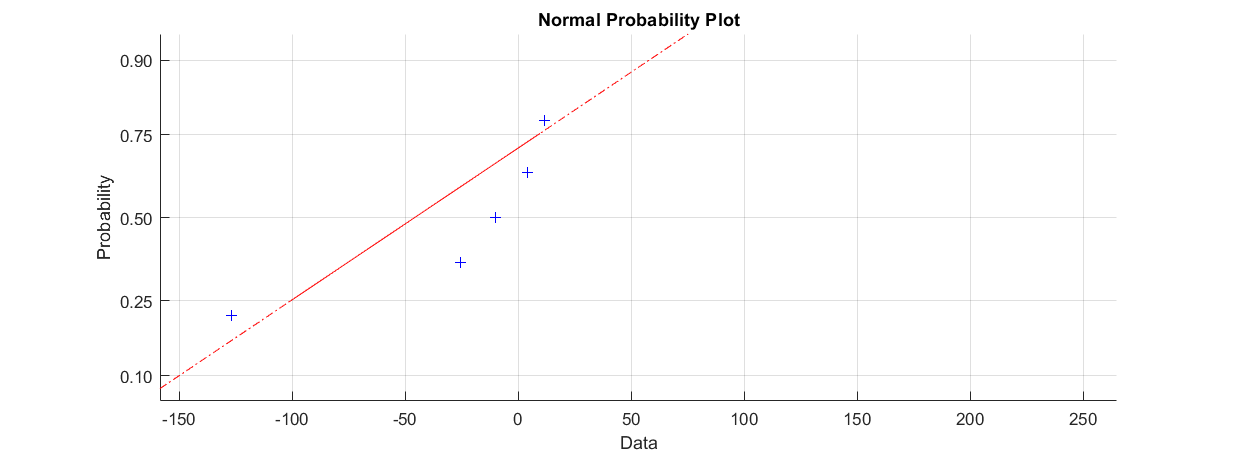

normplot(effects)

From the Normal Probability Plot, those terms that do not lie on the straight line - according to the "fat pencil test" criteria, are: D, AC, and AD.

Therefore, those terms are said to be statistically significant.

Step 6. Plot residuals

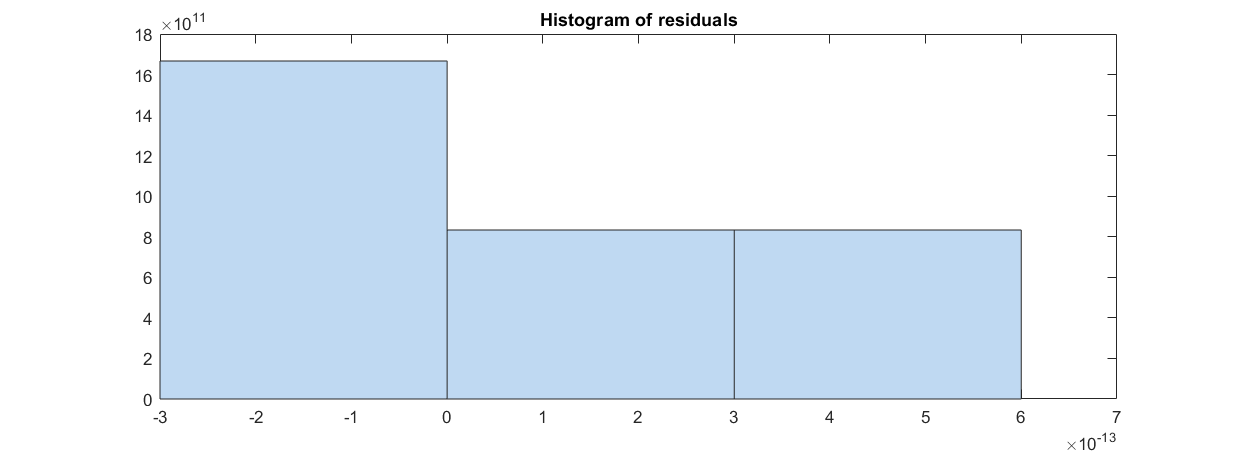

plotResiduals(mdl4)

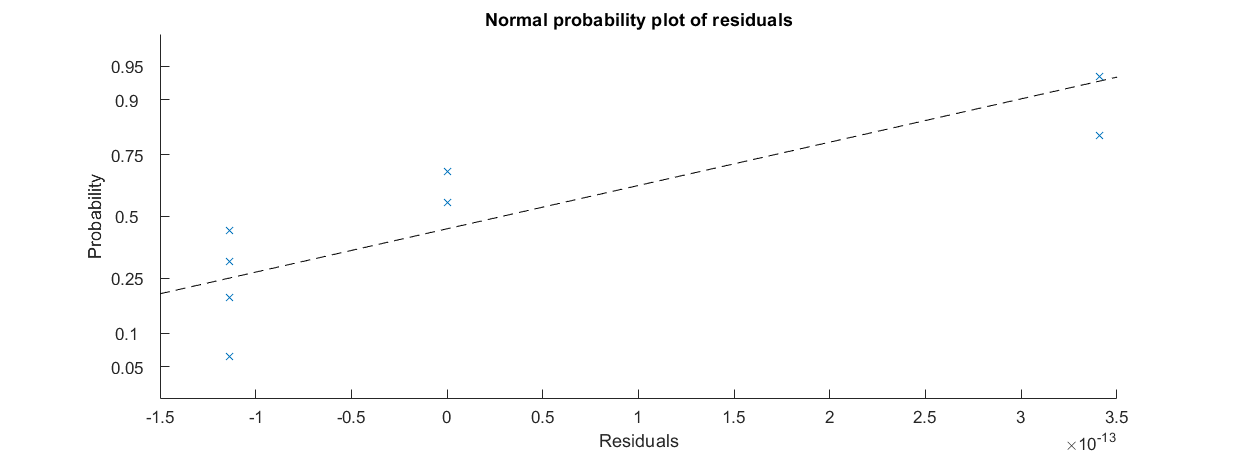

plotResiduals(mdl4,'probability')

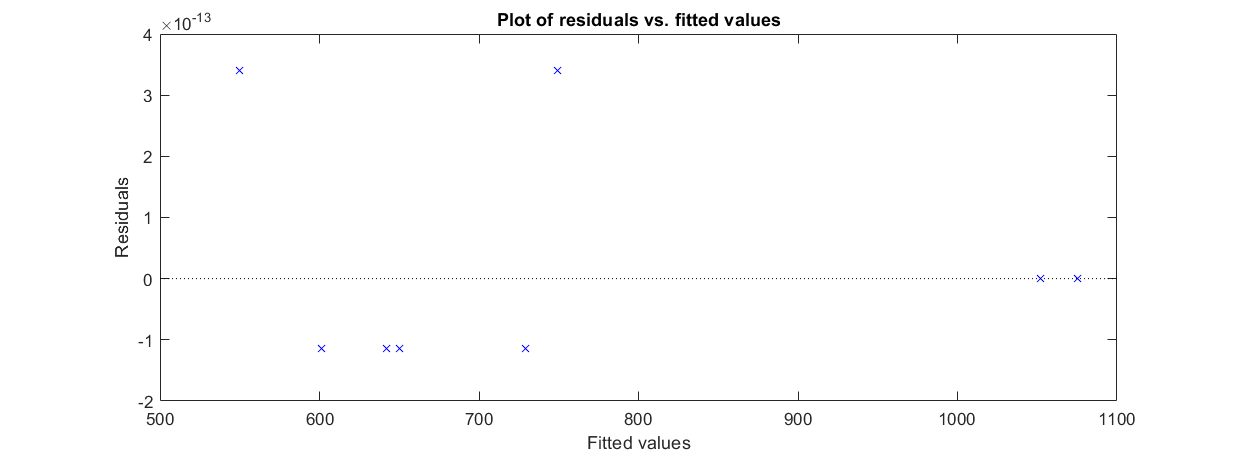

plotResiduals(mdl4,'fitted')

The generated histogram of residuals plot shows a skew to the left, indicating the normality assumption is not valid / the model adequacy is low.

Plot of residuals vs fitted values: The spread of residuals is much larger on the left of the problem domain when compared to the right side, indicating the model is a poor fit of the data in the left domain. - Similar conclusion for the Normal probability of residuals.

Recommendation: Because we have identified the statistically significant factors based off the Normal Probability Plot, it is recommended to "collapse" the experimental design to include only those terms; e.g. design a full factorial DOE with only those statistically significant terms (D, AC, and AD). Then re-run the experiement.